## 1D Wave equation

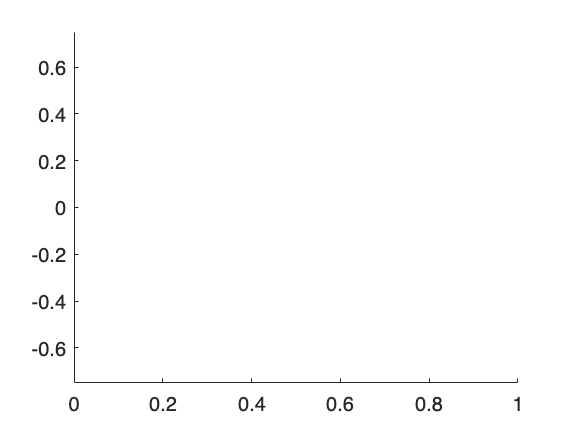

% Define parameters
fs = 44100;
k = 1 / fs;
kappa = 0.5;
f0 = 150;
sigma0 = 0.05;
sigma1 = 0.05;
L = 1;
c = 2 * L * f0;
lengthSound = fs; % Length in sound in samples


h = sqrt((c^2 * k^2 + 4*sigma1 * k + sqrt((c^2*k^2 + 4*sigma1 * k)^2 + 16*kappa^2*k^2)) / 2); % Stability condition
N = floor(L / h);
h = L / N; % Doing the second recalculation for h because of the tuning of the
lambda = c * k / h;

% State vectors
uNext = zeros(N+1, 1); % u^(n+1)_l
u = zeros(N+1, 1); % u^n_l
u(3:9) = hann(7);
uPrev = u;


% ((-k^2 * kappa^2) / h^4) * (u(l+2) - 4 * u(l+1) + 6 * u(l) - 4 * u(l-1) + u(l-2));
output = zeros(lengthSound, 1);

% Time-stepping loop
for n = 1:lengthSound
    for l = 3:N-1
        uNext(l) = (2 * u(l) - uPrev(l)  ...
            + ((c^2 * k^2) / h^2) * (u(l+1) - 2*u(l) + u(l-1))  ...
            - (kappa^2 * k^2 / h^4) * (u(l+2) - 4 * u(l+1) + 6 * u(l) - 4 * u(l-1) + u(l-2)) ...
            + sigma * k * uPrev(l) ...
            + (2 * sigma1 * k / h^2) * (u(l+1) - 2*u(l) + u(l-1) - uPrev(l+1) + 2*uPrev(l) - uPrev(l-1))) ...
            / (1 + sigma * k);
    end

    % plot(u);
    % drawnow;
    ylim([-0.75, 0.75]);

    output(n) = u(floor(N/5));

    uPrev = u;
    u = uNext;
end


soundsc(output, fs);